**4.1.3 Part c**

**A secret ‘hidden’ function eddieSecretFunction.p will be provided for you to experiment with. Explore the minimisation of this function with appropriate toolbox routines and describe your investigation.**

Initial investigation of the function reveals that the function is stochastic in nature - the same input will provide different outputs every time you run it

x = [2;4];
eddieSecretFunction(x)

ans = 59.4118

eddieSecretFunction(x)

ans = 337.0368

As can be seen, the results vary massively. A suitable approach to solving a stochastic function is using a stochastic based algorithm such as particleswarm.

nvars = 2;
% Algorithm can only supply row vector inputs so input has to be
% transformed to input to secret function
fun = @(x) eddieSecretFunction(x');

% Tweaking hyper parameters
options = optimoptions("particleswarm",...
    'MaxIterations', 1000, ...
    'Display','none', ...
    'SwarmSize', 100);
    
% Apply solver
[x, fval] = particleswarm(fun,nvars,[],[],options)

x =    -0.9981    3.9380


fval = 9.8132

[x, fval] = particleswarm(fun,nvars,[],[],options)

x =     1.9754    3.0122


fval = 1.2681

However running that twice also yields different minimum values. Should you run this code 1000 times and log the responses, interesting trends begin to occur.

% Load pre-calculated data
load("bulkAnalysis.mat")
disp(['Overall minimum is: ' num2str(min_fval) ' located at ' ...
    'position: ' num2str(min_x(1)) ', ' num2str(min_x(2))])

Overall minimum is: 0.014239 located at position: 1.9943, 3.9994


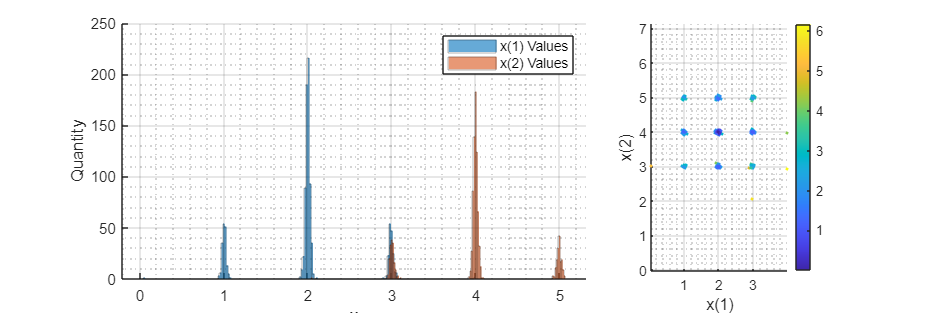

functions.plotStochastic(allMinimum)

Focusing on the peak found at position 2 as the most extreme minimu and removing the rows found at 1 and 3.

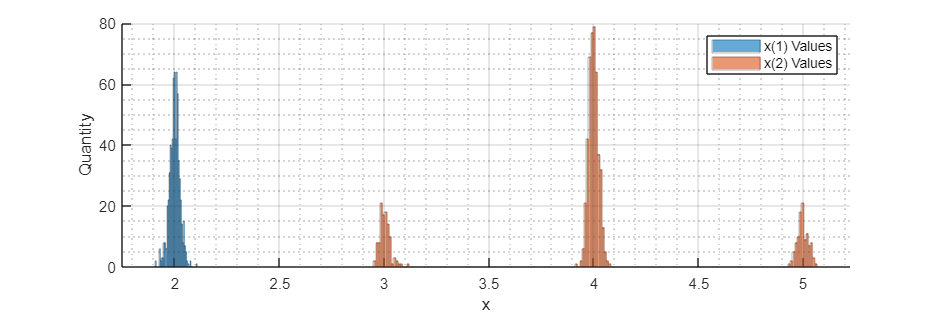

% Find indices of relevant data points
idx = find(allMinimum(:,1) > 1.5 & allMinimum(:,1) < 2.5);
% Extract rows required
filteredMinimum = allMinimum(idx, :);
functions.plotFilteredHist(filteredMinimum)

It can be seen that there is at least 3 minima located at positions (2,3), (2,4) and (2,5)

As these values were calculated, any minima found that were within a 0.1 of the current global minima were saved. They can be visualised in the next plot.

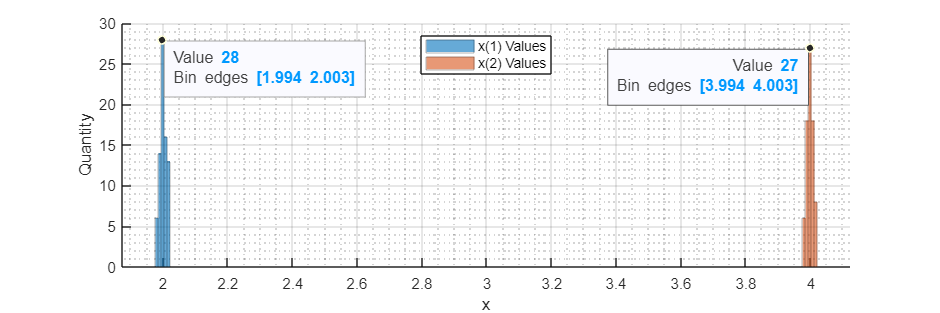

functions.plotExtremeMinima(extremeMinima)

It is a reasonable assumption to assume that the minima of the function is is located in the bins of [1.994 - 2.003] for x(1) and in [3.995 - 4.003] for x(2) which holds true for the calclated minima over time x = [1.9943, 3.9994]. 

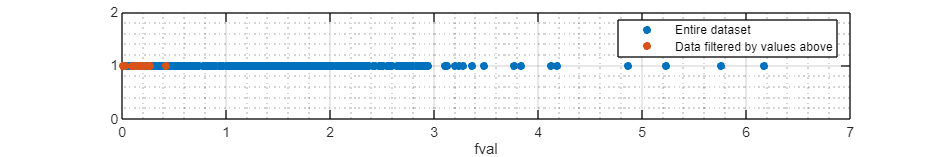

x1bin = [1.994  2.003];
x2bin = [3.995  4.003];

% Filter bin 1
idx = allMinimum(:,1) > x1bin(1) & allMinimum(:,1) < x1bin(2);
filteredMinimum = allMinimum(idx,:);
% Filter bin 2
idx = find(filteredMinimum(:,2) > x2bin(1) & filteredMinimum(:,2) < x2bin(2));
filteredMinimum = filteredMinimum(idx,:);

functions.plotFiltered(allMinimum, filteredMinimum)

The objective value of the function approaches zero around the co-ordinate bins of [1.994 - 2.003] for x(1) and in [3.995 - 4.003] for x(2). However the stochastic nature makes it impossible to submit a specific co-ordinate.